## Mesh processing toolbox

### Author & support : nicolas.douillet (at) free.fr, 2020-2023.

### Example #1 : vertex normals

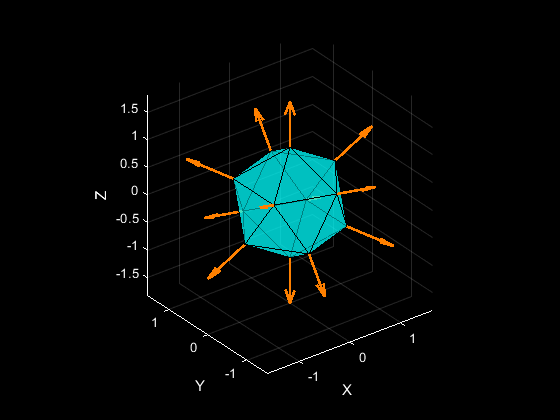

addpath('data/');
addpath('src/');

load('icosahedron.mat');
ngb_degre = 1;
select_vertex_normals(V,T,ngb_degre);

### Example #2 : non manifold triangles

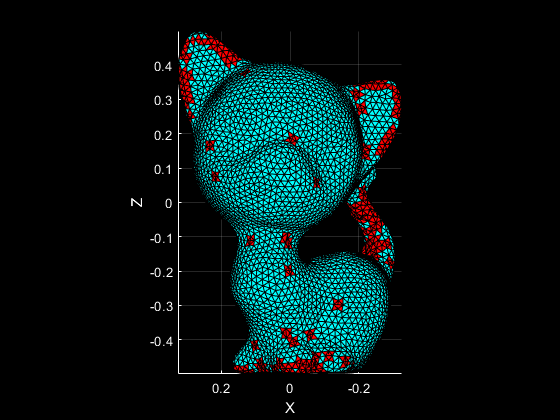

load('kitten_nmnfld.mat');
nmnfld_tgl_idx_list = select_non_manifold_triangles(V,T);
view(180,0);

### Example #3 : connected components

load('kitten_components.mat');
[cc_nb,components] = segment_connected_components(T);

4 components found in 1.406810e+00 seconds.


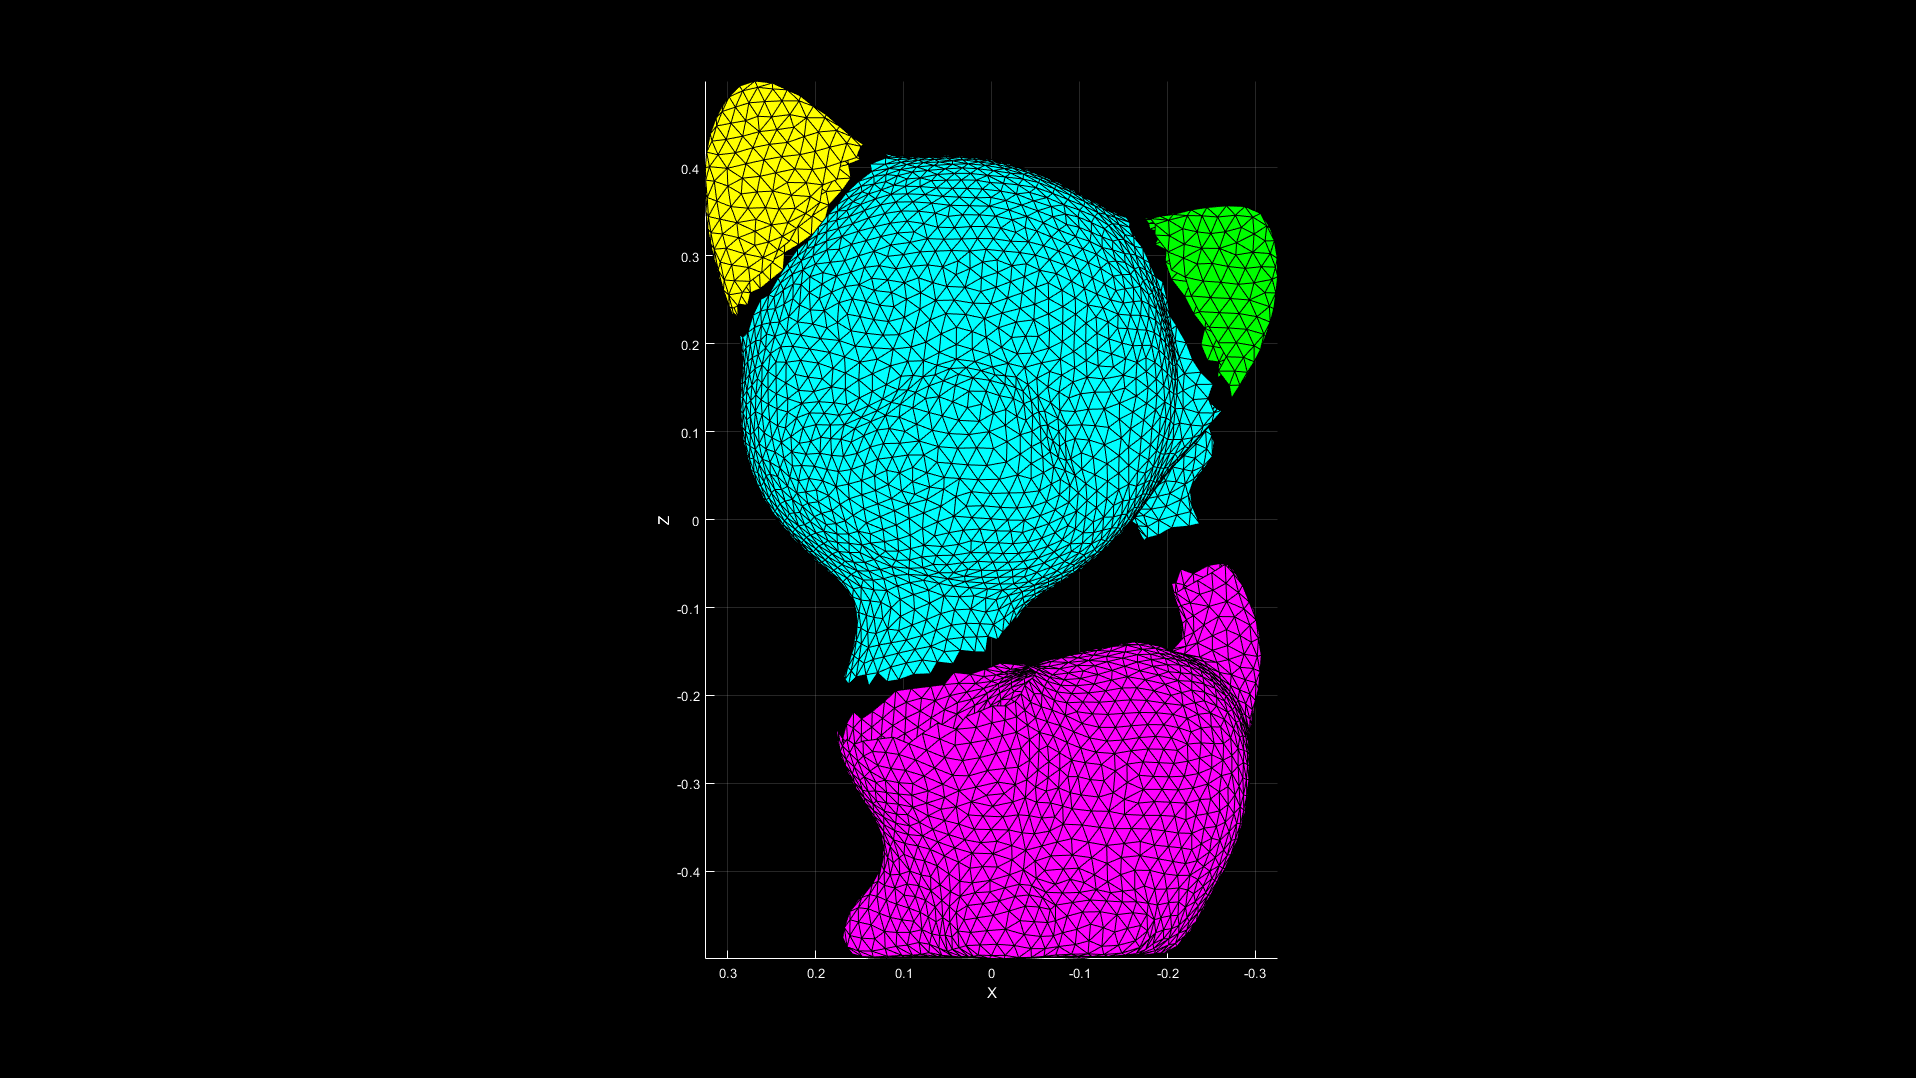

show_mesh_components(V,components);
view(180,0);

### Example #4 : boundaries and holes selection

load('kitten_holed.mat');
nmnfld_vtx_idx = select_non_manifold_vertices(V,T,false);
[V,T] = clone_solve_nmnfld_vertices(V,T,nmnfld_vtx_idx);

1 components found in 5.653400e-03 seconds.
1 components found in 1.173600e-03 seconds.
1 components found in 1.125700e-03 seconds.
1 components found in 6.359200e-03 seconds.
2 components found in 4.652400e-03 seconds.
duplicate_nmnfld_vertices request executed in 5.527780e-02 seconds. 5 clone vertices added.


boundaries = select_mesh_boundaries_and_holes(V,T);

6 boundaries detected in 6.997980e-02 seconds.


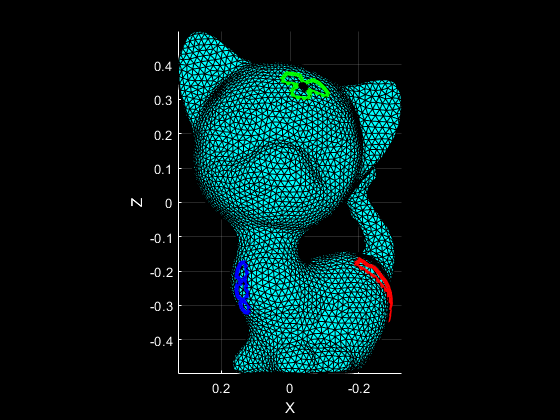

view(180,0);

### Example #5 : hole filling

[V,T] = remove_non_manifold_vertices(V,T);

0 non manifold vertices removed in 7.866321e-01 seconds.


boundaries = select_mesh_boundaries_and_holes(V,T);

6 boundaries detected in 5.761700e-02 seconds.


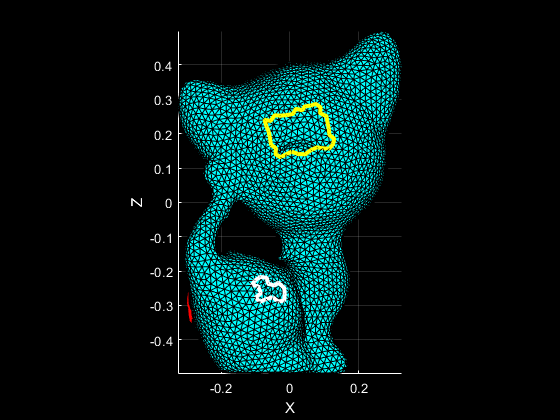

view(0,0);


max_perim_sz = 200;
T = fill_mesh_holes(V,T,boundaries,max_perim_sz);

6 hole(s) filled by adding 121 triangles in 4.912823e-01 seconds.


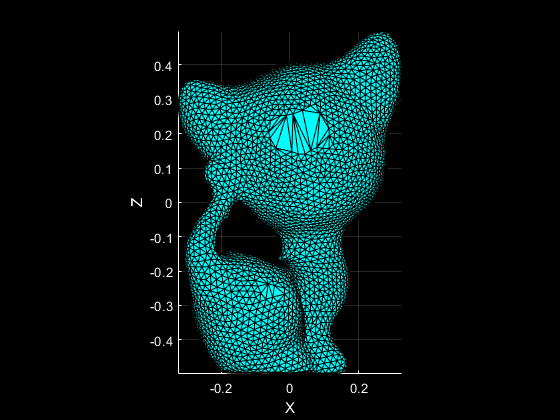

plot_mesh(V,T);
view(0,0);

### Example #6 : curvature

load('kitten.mat');
ngb_degre = 2;
N = compute_vertex_normals(V,T,ngb_degre,'raw');
curvature = compute_mesh_curvature(V,T,N,ngb_degre,'mean');

mean curvature computed in 6.429779e-01 seconds.


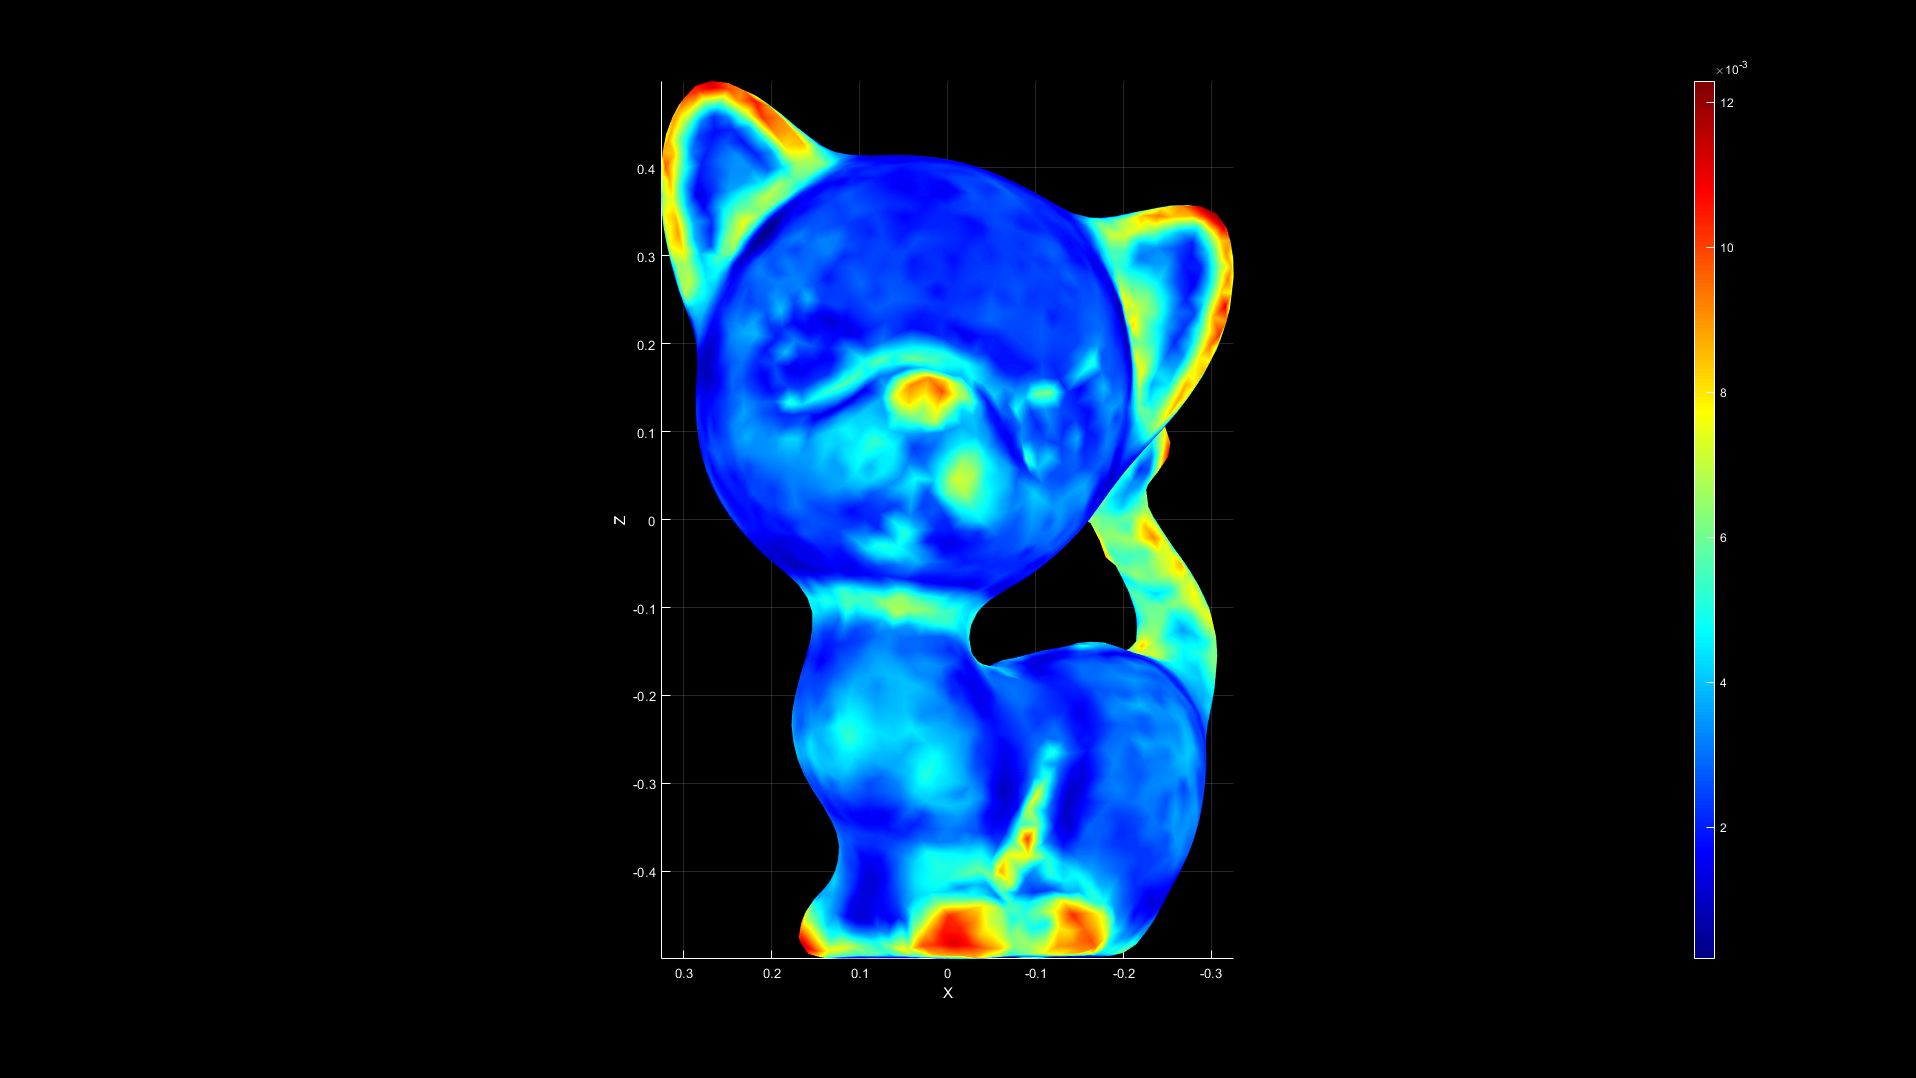

show_mesh_curvature(V,T,curvature);
view(180,0);

### Example #7 : subselection

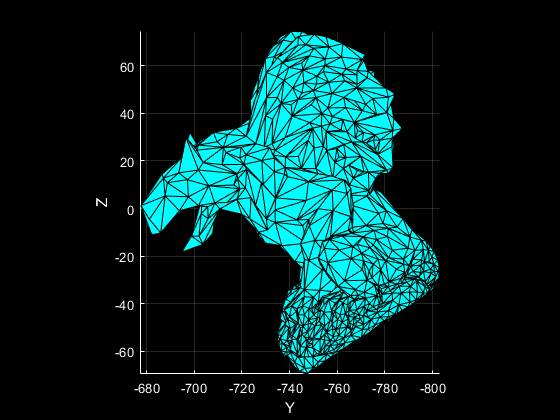

load('Gargoyle_3k.mat');
plot_mesh(V,T);
view(-90,0);


n = [0 1 1];
I = [-23 -751 -13];
[V_out,T_out] = select_submesh(V,T,n,I); % Gargoyle top part 

submesh with 586 vertices and 3372 triangles selected in 2.901240e-02 seconds.


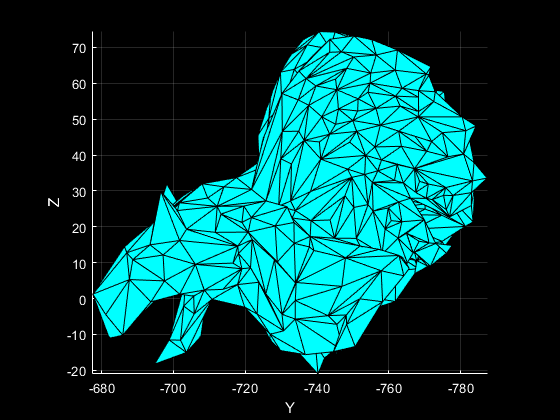


plot_mesh(V_out,T_out);
view(-90,0);

### Example #8 : smoothing

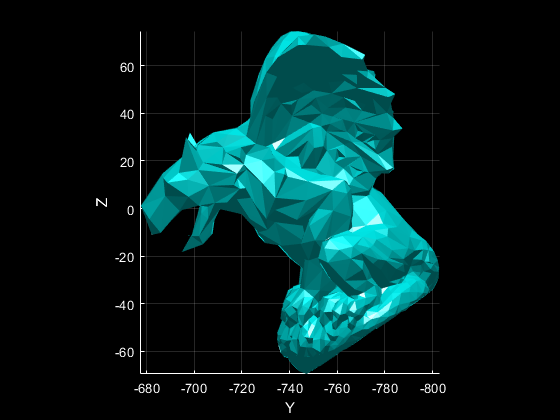

plot_mesh(V,T), shading interp, camlight left;
view(-90,0);


N = compute_vertex_normals(V,T,2);
nb_iterations = 1;
ngb_degre = 1;
V = smooth_mesh(V,T,nb_iterations,ngb_degre);

Laplacian mesh smoothed in 5.866040e-02 seconds.


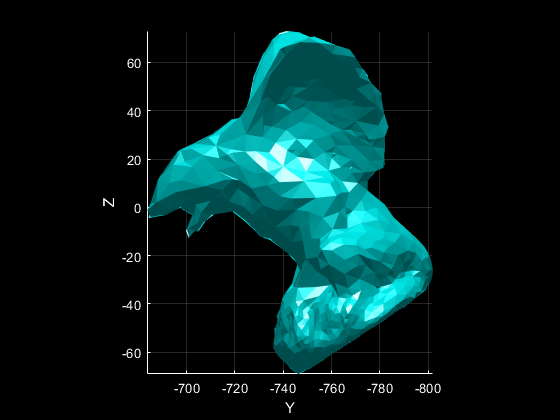


plot_mesh(V,T), shading interp, camlight left;
view(-90,0);

### Example #9 : convex hull

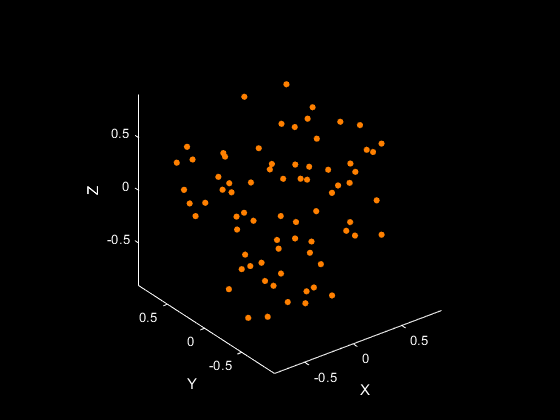

nb_vtx = 128;
X = 2*(rand(nb_vtx,1)-0.5);
Y = 2*(rand(nb_vtx,1)-0.5);
Z = 2*(rand(nb_vtx,1)-0.5);

Rho = X.^2 + Y.^2 + Z.^2;
i = Rho <= 1;
X = X(i);
Y = Y(i);
Z = Z(i);
V = cat(2,X,Y,Z);

plot_point_set(V,'o',[1 0.5 0],4);
axis equal;
view(3);


[V,Qh] = quick_hull(V);

Mesh quick hull computed in 5.304490e-01s.


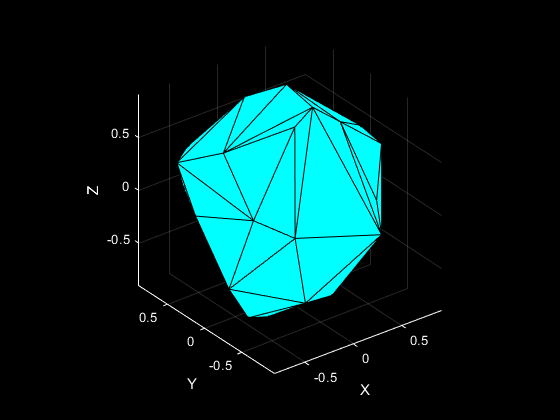

plot_mesh(V,Qh);
axis equal;
view(3);

### Example #10 : boundary smoothing

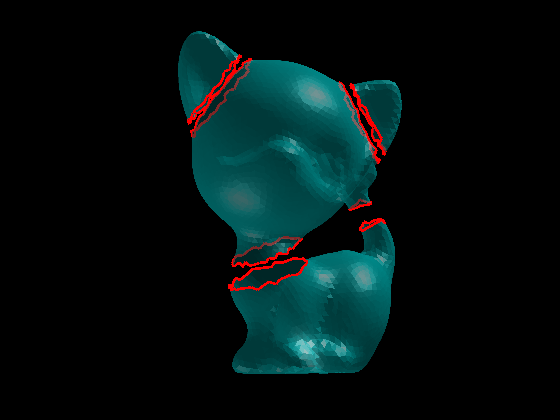

load('kitten_components.mat');

show_mesh_boundaries_and_holes(V,T);
shading interp;
camlight left;
alpha(0.5);
view(180,0);
axis off;


boundaries = detect_mesh_boundaries_and_holes(T);

8 boundaries detected in 5.799910e-02 seconds.



nb_iterations = 2;
ngb_degre = 6;
V_out = smooth_mesh_boundaries_and_holes(V,boundaries,nb_iterations,ngb_degre);

Mesh boundaries smoothed in 9.875100e-03 seconds.


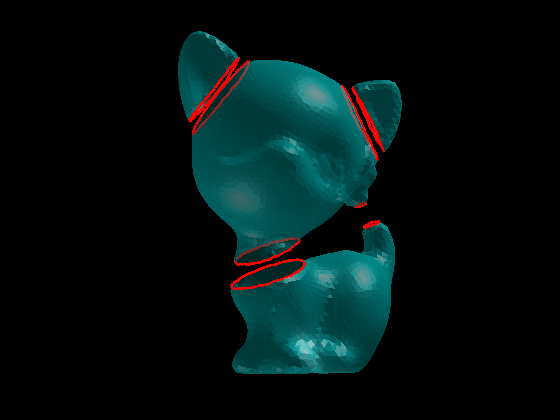


show_mesh_boundaries_and_holes(V_out,T);
shading interp;
camlight left;
alpha(0.5);
view(180,0);
axis off;